## Task 1

range of alpha values

alpha = 0:0.01:pi/2;

eta = 0.1

d1 = (cos(alpha) + 0.1) ./ sin(alpha);

eta = 1.1

d2 = (cos(alpha) + 1.1) ./ sin(alpha);

plot results

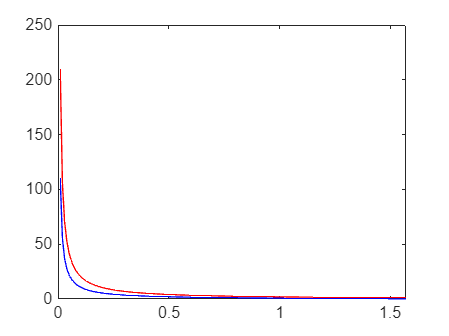

plot(alpha, d1, 'b', alpha, d2, 'r')

## Task 2

Definiramo newtonovo metodo

function root = newton_method(f, df, x0, tol, max_iter)
x = x0;
iter = 0;
while iter < max_iter
    x_new = x - f(x) / df(x);
    if abs(x_new - x) < tol
        root = x_new;
        return;
    end
    x = x_new;
    iter = iter + 1;
end
root = x;
end

d(alfa) in odvod

d = @(alpha, eta) (cos(alpha) + eta) ./ sin(alpha);
dd = @(alpha, eta) (-sin(alpha) - eta * cos(alpha)) ./ (sin(alpha))^2;
tol = 1e-6;
 
eta_values = 0.1:0.1:0.9;
optimal_angles = zeros(size(eta_values))

optimal_angles =      0     0     0     0     0     0     0     0     0


 
for i = 1:length(eta_values)
     eta = eta_values(i);
     x0 = pi / 4 + eta * 0.1;
     optimal_angles(i) = newton_method(@(alpha) dd(alpha, eta), @(alpha) -dd(alpha, eta), x0, tol, 10);
end
 
disp(optimal_angles);

   10.7954   10.8054   10.8154   10.8254   10.8354   10.8454   10.8554   10.8654   10.8754



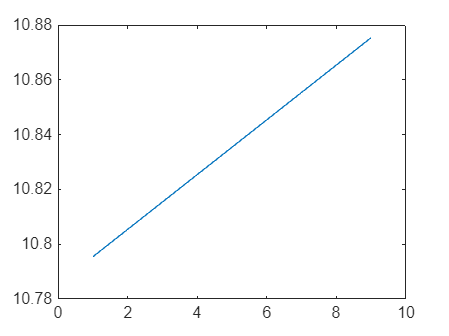

plot(optimal_angles)